clear
%logistic Regression Simulation
% set seed to same default value
rng('default')
% set true linear coefficients
beta0tru = -6; 
beta1tru = 0.2;
% select indepedent x values
dx = 2; 
x = (10:dx:60)';
n = length(x);
% generate dichotomous values
p = 1./(1 + exp(-beta0tru - beta1tru.*x));
y=binornd(ones(n, 1), p);
% Grid search values 
beta0min =-10; 
beta0max = -3; 
beta1min = -4; 
beta1max = 4; 
beta0del = 0.01; 
beta1del = 0.01;
beta0 = (beta0min:beta0del:beta0max)';
beta1 = (beta1min:beta1del:beta1max)';
m0 = size(beta0, 1); 
m1 = size(beta1, 1);
% try all beta0, beta1 values 
maxLL = -10^6; 
LL = ones(m0, m1);
beta0hat = 0; 
beta1hat = 0;
for i = 1 : m0
    for j = 1 : m1
        LL(i, j) = sum(y.*(beta0(i, 1) + beta1(j, 1)*x)) ... 
        - sum(log(1 + exp(beta0(i, 1) + beta1(j, 1)*x)));
        if (LL(i, j) > maxLL)
            beta0hat = beta0(i, 1);
            beta1hat = beta1(j, 1);
            maxLL = LL(i, j);
        end
    end
end
beta0hat

beta0hat = -6.8100

beta1hat

beta1hat = 0.2200


phat = 1./(1 + exp(-beta0hat - beta1hat.*x))

phat =     0.0099
    0.0152
    0.0234
    0.0359
    0.0547
    0.0824
    0.1224
    0.1780
    0.2516
    0.3430


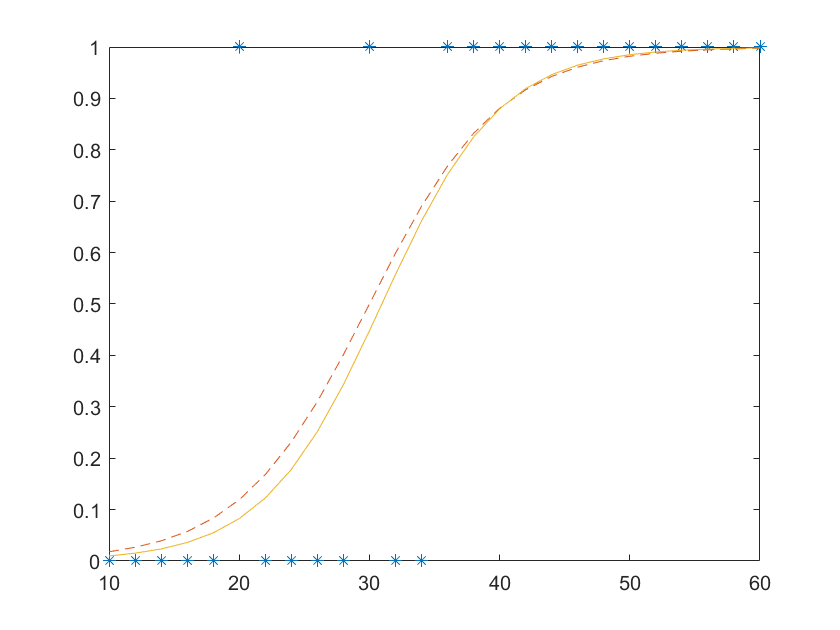


plot(x, y, '*')
hold on
plot(x, p, '--')
plot(x, phat)
hold off


for i = 1 : m0
    for j = 1 : m1
        LL(i, j) = sum(y.*(beta0(i, 1) + beta1(j, 1)*x)) ... 
        - sum(log(1 + exp(beta0(i, 1) + beta1(j, 1)*x)));

    end
end
LLtrue=sum(y.*(beta0tru + beta1tru*x)) - sum(log(1 + exp(beta0tru + beta1tru*x)))

LLtrue = -7.3035

LLhat=sum(y.*(beta0hat + beta1hat*x)) - sum(log(1 + exp(beta0hat + beta1hat*x)))

LLhat = -7.2193

[B1H, B0H]=meshgrid(beta1, beta0);
s = surf(B1H, B0H, LL)

s =   Surface - 属性:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [701×801 double]
           YData: [701×801 double]
           ZData: [701×801 double]
           CData: [701×801 double]

  显示 所有属性


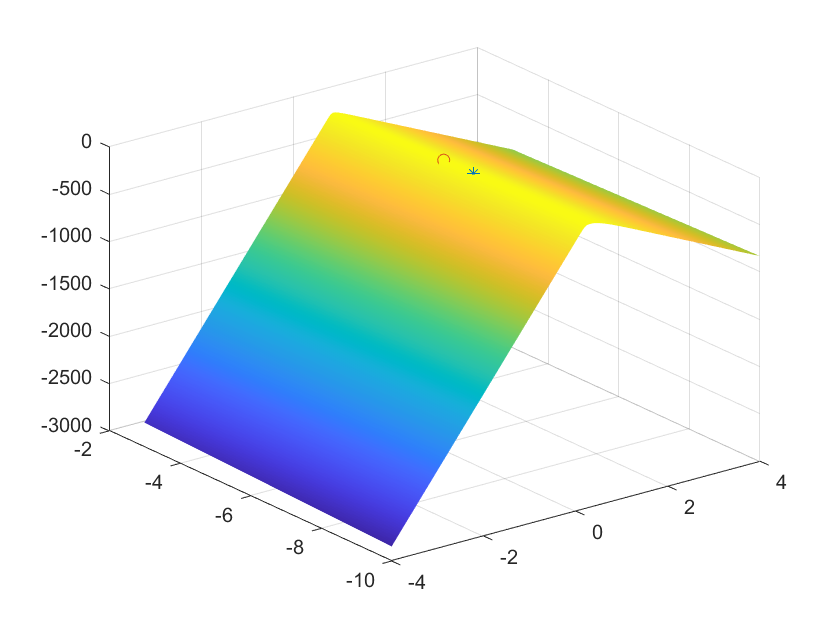

s.EdgeColor = 'none';
hold on
plot3(beta1hat, beta0hat, LLhat, '*')
plot3(beta1tru, beta0tru, LLtrue, 'o')
hold off 